# Cancer Classification using Machine Learning

In this workshop you will learn the fundamentals of machine learning to develop a classifier capable of discriminating normal tissue from cancerous tissue. To do so, we will be working with data captured during a surgical procedure using an endoscopic near-infrared fluorescence imaging system. This system simultaneously captures and displays videos in both the visible white-light and near-infrared spectrums.

Although in general pixel-by-pixel classification is possible (e.g. [semantic segmentation](https://www.mathworks.com/solutions/image-video-processing/semantic-segmentation.html)), for this problem such resolution can significantly increase computing and labeling requirements unnecessarily, and is more susceptible to signal noise (e.g. due to imperfect video stabilization). As such, we will be working with labeled grid regions - in this case, a grid of 18 x 24 = 432 regions. 

### Examine Labeled Regions

We'll begin by loading and displaying an example of a video frame that has already labeled grid regions as "cancer" (red) or "negative" (blue) based on test results and clinician expertise. Although unavailable in MATLAB Online, this can be done using the [Image Labeler](https://uk.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html) app in the desktop version of MATLAB.

load( "AMST_0001.mat", "time", "Iregion", "cframe1", "region", "LabelTable" )

cmap = lines( max(LabelTable.Selection) );
lid = LabelTable.Selection; % label IDs
gid = LabelTable.("Grid Region"); % grid region IDs

labeled = insertRegions( cframe1, region(gid,:), ...
    Color=255*cmap(lid,:), LineWidth=2 );

figure
imshow( labeled )
title( "Color-Coded Region Labels" )

As you will see later, training a classifier will require many more labeled images, representing many different patients. You can use an [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) to manage a collection of image files and access them in the Image Labeler app.

### Examine Labeled Intensity Time Histories

In the previous section we also loaded the fluorescence intensity time histories across all 432 grid regions. We can help reduce noise in the extracted fluorescence intensity time histories using the [`smoothdata`](https://www.mathworks.com/help/matlab/ref/smoothdata.html) function (along time, dimension 1). Each signal is then color-coded to match its corresponding labeled grid region in the previous figure (or grayed out if unlabeled).

Ismooth = smoothdata( Iregion, 1, SmoothingFactor=0.1 );

figure
plot( time, Ismooth, Color=0.85*[1 1 1], SeriesIndex="none" );
hold on; grid on
colororder( cmap(lid,:) )
h = plot( time, Ismooth(:,gid), LineWidth=1 );
axis padded

[labels,idx] = unique( LabelTable.Label, "stable" );
legend( h(idx), labels, Location="southeast" )
title( "Smoothed Intensity Time Histories" )
xlabel( "Video Time (sec)" )
ylabel( "Fluorescence Intensity [0 - 255]" )

### Extract Features of Interest

Next, we'll use the [`getPredictors`](matlab:open('..\helper\getPredictors.m')) and [`plotFeatures`](matlab:open('..\helper\plotFeatures.m')) helper functions to extract and display the following features of interest:

- `Ibase` - base intensity value (just before start of ICG dye absorption)

- `Ipeak` - peak intensity value

- `dThalf` - time to reach half peak intensity (from start of absorption)

- `dTpeak` -  time to reach full peak intensity (from start of absorption)

- `IdecayXs` - intensity value "`X`" seconds after peak intensity

dTdecay = [50 100 145]; % time since peak intensity
features = getPredictors( time, Ismooth(:,gid), dTdecay );

hold on
plotFeatures( features )
hold off
title("Extracted Features")

disp( [LabelTable(:,"Label") features(:,2:end)] )

Now that we’ve extracted intensity time histories from the surgical videos, we can train a classifier to differentiate if each of these signals exhibits characteristics representative of cancer or negative tissue.

### Develop a Model using the Classification Learner

The above process was repeated for a total of 22 patients. We will use 20 of the videos for training (10 with cancer and 10 without) and set aside 2 videos for testing (1 with cancer and 1 without).  On average, each video labeled about a dozen grid regions. "Negative" regions were collected from all videos, with an even mix of benign lesions and healthy tissue.

Load training and testing data sets and check if training data set is balanced.

load( "FluorescenceDataSets.mat", "trainData", "testData" )

TrainingCount = countlabels(trainData.Label)
TestCount = countlabels(testData.Label)

Open the [**Classification Learner**](https://www.mathworks.com/help/stats/classification-learner-app.html) from the APPS tab to begin developing a classifier.

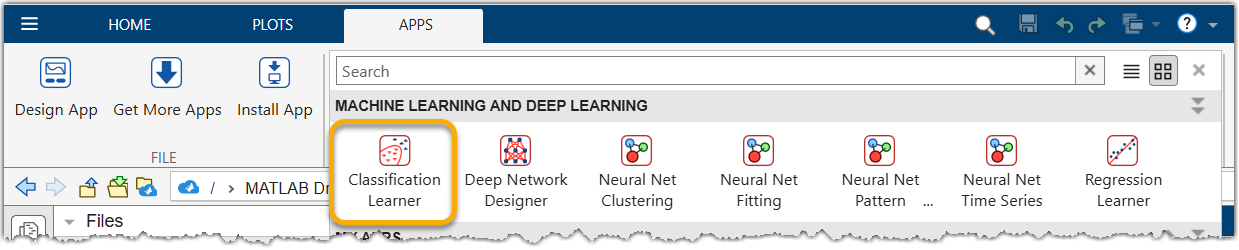

From the LEARN tab:

- **New Session** >> **From Workspace** >> **Data Set Variable**: `trainData` (unselect "Patient") >> **Start Session**

- *Select* **Feature Selection** to explore Feature Ranking Algorithms

- From the MODELS section, *select* **All** (models) >> *select* **Train All** >> **Sort by**: *Accuracy (Validation)*

- *Select model* >> from PLOTS AND RESULTS section, *select* **Confusion Matrix**

From the TEST tab:

- **Test Data** >> **From Workspace** >> **Test Data Set Variable**: `testData` >> **Import**

- From the TEST section, *select* **Test All**

- *Select model* >> from PLOTS AND RESULTS section, *select* **Confusion Matrix**

See the EXPLAIN tab to explore [interpretability techniques](https://www.mathworks.com/discovery/interpretability.html).

### Export and Test the Trained Model

We can reproduce the test confusion matrix we created in the Classification Learner app by [exporting the model](https://www.mathworks.com/help/stats/export-classification-model-for-use-with-new-data.html) and using it to make predictions on the test data. 

From the LEARN tab: select the desired model, *select* **Export Model** >> **Variable Name**: `trainedModel` >> **OK**.

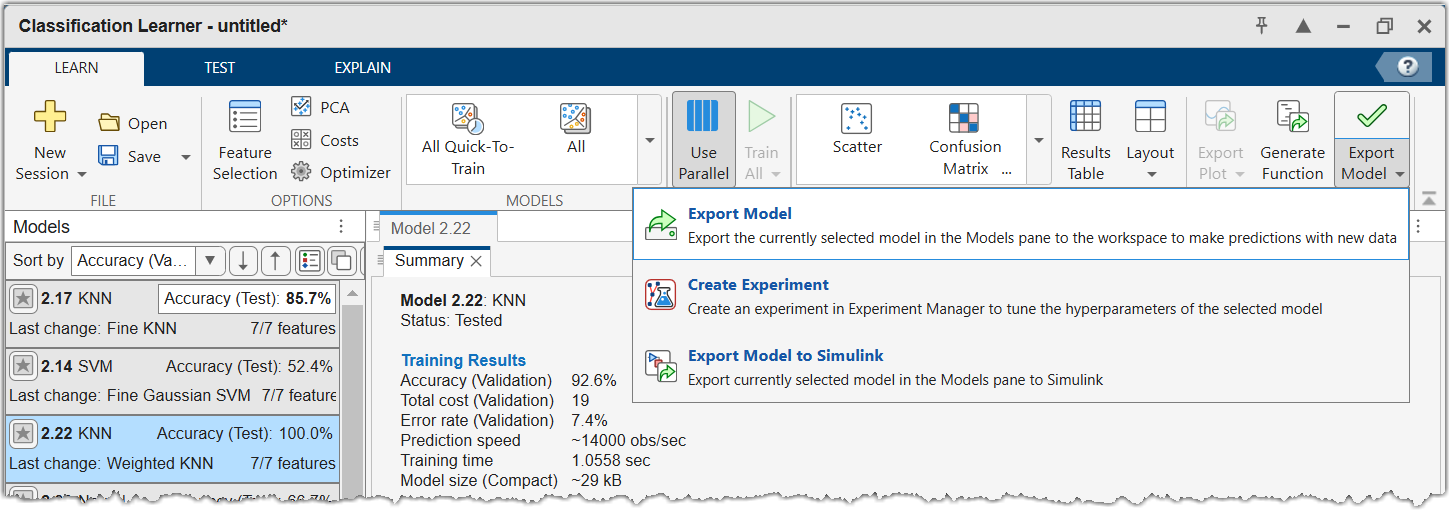

if ~exist( "trainedModel", "var" ) % not exported from Classification Learner
    load( "KnnClassifier.mat", "trainedModel" )
end

The exported `trainedModel` is a structure containing information about the model, a classification object, and a function for making predictions (`trainedModel.predictFcn`). Alternatively, the classification object can be extracted from the structure and used directly. The name of the classification object will varying depending on the type of model, but as it always contains "Classification," can be generically extracted as follows.

flds = fields( trainedModel );
idx = contains( flds, "Classification" );
model = trainedModel.(flds{idx})

We can then use the classification object's [`predict`](https://www.mathworks.com/help/stats/classificationknn.predict.html) method to classify the test data and recreate the test [confusion chart](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html).

predLabel = predict( model, testData );

figure
confusionchart( testData.Label, string(predLabel) )
title( "Test Accuracy = " + 100*mean( testData.Label==predLabel ) + "%" )

### Use Scores to Create Prediction Heatmap

The prediction function can also provide the classification scores as a second output. The classification `score(i,j)` represents the posterior probability that the `i`th observation belongs to class `j`. Since we gathered intensity time histories from a grid of regions across the entire video frame, we can use the classification scores to create a prediction probability heatmap.

To do so, we will repeat the following steps for each patient video from the test data.

- Reduce noise in intensity time history for each grid region (`smoothdata`)

- Extract features for each grid region ([`getPredictors`](matlab:open('..\helper\getPredictors.m')))

- Use trained `model` to compute classification score for each grid region (`predict`)

- Interpolate scores from grids to pixels and map values to colors ([`predictionOverlay`](matlab:open('..\helper\predictionOverlay.m')))

Note, if there was excessive camera movement, intensity data may not be available along some edges due to image warping during the registration process.

classNames = string( model.ClassNames );
cmap = turbo; % color map: Negative -> blue, Cancer -> red
if (classNames(1) == "Cancer")
    cmap = flip( cmap );
end

testIds = unique( [testData.Patient] );
for k = 1:numel( testIds )
    % Load intensity time histories for each grid region
    load( testIds(k)+".mat", "time", "Iregion", "cframe1", "region" )

    % 1) Reduce noise in intensity time history for each grid region
    Ismooth = smoothdata( Iregion, 1, SmoothingFactor=0.1 );

    % 2) Extract features for each grid region
    features = getPredictors( time, Ismooth, dTdecay );
    val = ~any( isnan( features.Variables ), 2 );
    features = features(val,:); % only use valid regions

    % 3) Compute classification scores for each grid region
    [~,score] = predict( model, features );

    % 4) Interpolate scores from grids to pixels and map values to colors
    overlay = predictionOverlay( cframe1, region, val, score, Colormap=cmap );

    % Create figure and colorbar
    fig = figure;
    imshow( overlay )
    colormap( cmap ); clim( [-1 1] )
    cbar = colorbar( "south", Ticks=[-1 1] );
    cbar.TickLabels = classNames;
    cbar.Position(2) = 0.05;
    title( "Prediction Heatmap" )

    % Add subtitle with biopsy result
    labels = testData.Label( testData.Patient==testIds(k) );
    if ismember( "Cancer", labels )
        lesion = "Cancer";
    else
        lesion = "Benign";
    end
    subtitle( "Lesion Biopsy: " + lesion, Visible="on" )
    fig.Position(4) = 1.2*fig.Position(4); % increase height
end

*Copyright 2024 The MathWorks, Inc.*